# Transition from 1D to 2D

clear all, close all, clc
set_defaults()

## Dimension independent syntax

One benefit of the operator implementation is that it hides the details of the coordinate system and spatial dimensions similar to the dyadic notation (div, grad, curl). Consider the instantaneous problem for a steady confined aquifer in both 1D and 2D:

PDE:        $-\nabla\cdot\left[K\nabla h\right]=q_p$     on   $x \in \left[0,\,1\right]\quad\times\quad y \in \left[0, 1\right]$

BC:         $\left.\mathbf{q}\cdot\hat{\mathbf{n}}_i\right|_{x=0} = 1$   and     $h(x,y=1) = 0$.

The answer to this somewhat boring problem is simply: $h\left(x\right)=1-x$. 

This problem can be solved as a 1D or a 2D problems and we'll use it here to illustrate the differences between 1D and 2D implementations.

One of the main aims of the operator implementation is to hide the dimensionality and coordinate system in the same way that the dyadic notation hides these details. Therefore, nothing will change on the highest layer of your code - as demonstrated in the example below.

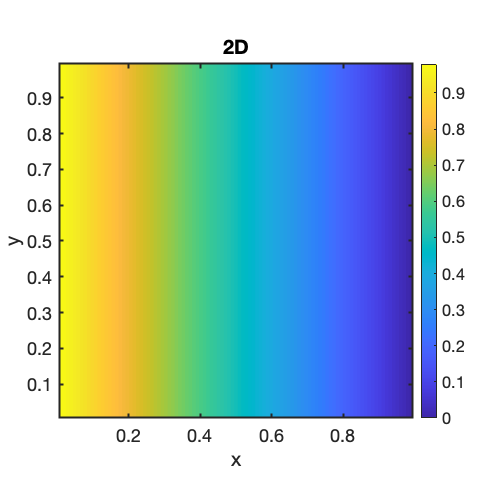

% Define the grid and operators
clear Grid
Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = 100;
Grid.ymin = 0; Grid.ymax = 1; Grid.Ny = 100;  % The only line that changes
% Grid.geom = 'cartesian';
Grid = build_grid(Grid);
[D,G,~,I,M] = build_ops(Grid);
L = -D*G; fs = spalloc(Grid.N,1,0);

% Define the boundary conditions
BC.dof_dir   = [Grid.dof_xmax];
BC.dof_f_dir = [Grid.dof_f_xmax];
BC.g         = [zeros(Grid.Ny,1)];
BC.dof_neu   = [Grid.dof_xmin];
BC.dof_f_neu = [Grid.dof_f_xmin];
BC.qb        = ones(Grid.Ny,1);
[B,N,fn] = build_bnd(BC,Grid,I);

% Solve for head
u = solve_lbvp(L,fs+fn,B,BC.g,N);

figure('position',[10 10 500 500])
% Plot solution (o.k., the plotting changes as well)
if Grid.Ny == 1
    plot(Grid.xc,u,'-')
    xlabel 'x', ylabel 'h'
else
    [X,Y] = meshgrid(Grid.xc,Grid.yc);
    [C,h] = contourf(X,Y,reshape(u,Grid.Ny,Grid.Nx),100); colorbar
    set(h,'LineColor','none')
    xlabel 'x', ylabel 'y', title '2D'
    axis equal
end

## Changes to main functions

Of course, the changes required to go from 1D to 2D are just hidden in the functions that have been called. The following functions you have written must be updated:

- `build_grid()`: need to add all the information about the 2D grid - substantial change (trivial)

- `build_ops()`: implement 2D operators - substantial change 

The following functions that do **not** need to be changed:

- `comp_mean()`

- `build_bnd()`

- `solve_lbvp()`

- `comp_flux()`

These functions don't change, because the BC's are implemented as an elimination of constraints, which is independent of dimension. Benefit of the slightly more abstract approach.

## Life is more interesting in 2D

Even the simple steady confined aquifer problem can be made more interesing in 2D with some heterogeneity. In general, the hydraulic conductivity is a function of x, so that


$$-\nabla\cdot\left[K(\mathbf{x})\nabla h\right] = 0$$


Here we generate a simple Gaussian conductivity field 

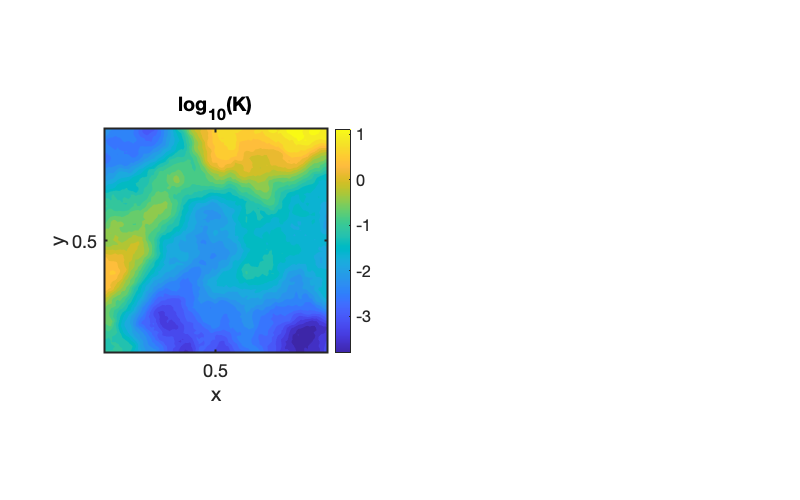

seed = 2061972;
sigma = 0.3;
rho = 1;
[logK,gamma,delta] = comp_matern(sigma,rho,Grid,D,G,I,seed);                   
logK = reshape(logK,Grid.Ny,Grid.Nx);

figure('position',[10 10 800 500])
subplot 121
[C,h2] = contourf(X,Y,logK,25); colorbar
set(h2,'LineColor','none')
set(gca,'xtick',[0 .5 1],'ytick',[0 .5 1])
xlabel 'x', ylabel 'y', title 'log_{10}(K)'
axis equal

Then we can solve for the 2D head variation with the same  boundary conditions as before. The head will preferentially drop in areas of low conductivity and be almost constant in region of high conductivity.

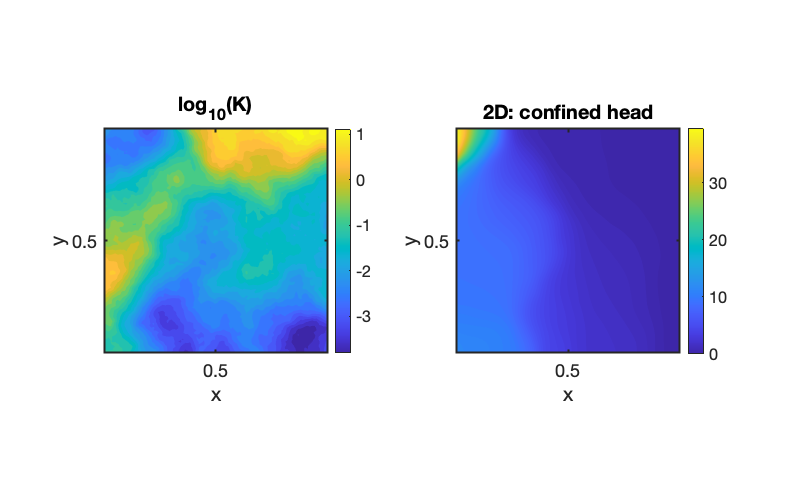

K = 10.^(logK(:));
Kd = comp_mean(K,M,-1,Grid,1);
L = -D*Kd*G;

% Solve for Head
u = solve_lbvp(L,fs+fn,B,BC.g,N);
subplot 122
[C,h3] = contourf(X,Y,reshape(u,Grid.Ny,Grid.Nx),100); colorbar
set(h3,'LineColor','none')
set(gca,'xtick',[0 .5 1],'ytick',[0 .5 1])
axis equal
xlabel 'x', ylabel 'y', title '2D: confined head'

Again this was achieved with minimal changes to the code, we simply had to add the Kd matrix into the linear operator, `L = -D*Kd*G`.

# Auxillary functions

## set_defaults()

function [] = set_defaults()
set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end

### comp_matern()

This is a function that computes correlated random fields with Matern covariances by solving the equivalent modified Helmholtz equation.

function [m,gamma,delta] = comp_matern(sigma,rho,Grid,D,G,I,seed) % MDOT repo

coeff = 3.6e-07; % handcrafted, locally sourced
% 6.3441e-06 - 1 by 1 domain
% 9.7629e-06 - 2 by 2 domain
% 9.0255e-06 - 3 by 3 domain
% 8.6570e-06 - 4 by 4 domain

gamma =sqrt(coeff)/2*rho/sigma;
delta = 2*sqrt(coeff)/(rho*sigma);

L = -gamma*D*G+delta*I;
rng(seed);
fs = randn(Grid.N,1);

Param.dof_dir = [];
Param.dof_f_dir = [];
Param.g = [];
Param.dof_neu = [];
Param.dof_f_neu = [];
Param.qb = [];

[B,N,fn] = build_bnd(Param,Grid,I);
m = solve_lbvp(L,fs+fn,B,Param.g,N);
end
